# Euler Bernoulli beam with cubic spring and damper

Generate model

clear all;
nElements = 25;
kappa = 6; % cubic spring
gamma = -0.02; % cubic damping
[M,C,K,fnl,f_0] = build_model(kappa, gamma, nElements);
n = length(M);
% Dynamical system setup 

DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',3,'Nmax',10,'notation','multiindex')

We assume periodic forcing of the form


$$\mathbf{f}^{ext}(\phi) = \mathbf{f}_0\cos(\phi)=\frac{\mathbf{f}_0}{2}e^{i\phi} 
+ \frac{\mathbf{f}_0}{2}e^{-i\phi}  $$


epsilon = 0.002;

Fourier coefficients of Forcing

kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas,epsilon);
% Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 8.839900e-04
modal damping ratio for 2 mode is 5.485350e-03
modal damping ratio for 3 mode is 1.535575e-02

 The first 6 nonzero eigenvalues are given as 
   1.0e+02 *

  -0.0001 + 0.0700i
  -0.0001 - 0.0700i
  -0.0024 + 0.4387i
  -0.0024 - 0.4387i
  -0.0189 + 1.2283i
  -0.0189 - 1.2283i



**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','multiindex')
masterModes = [1,2]; 
S.choose_E(masterModes);

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304


(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

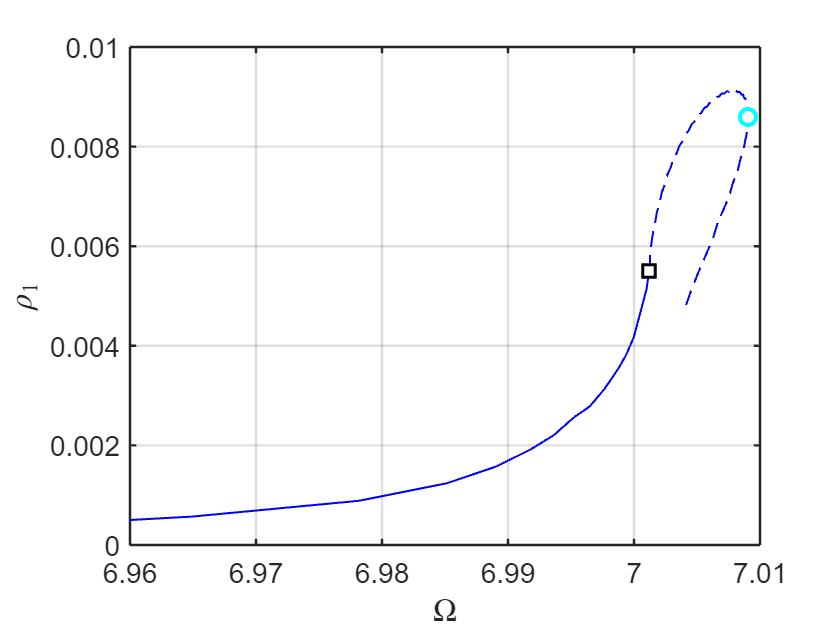

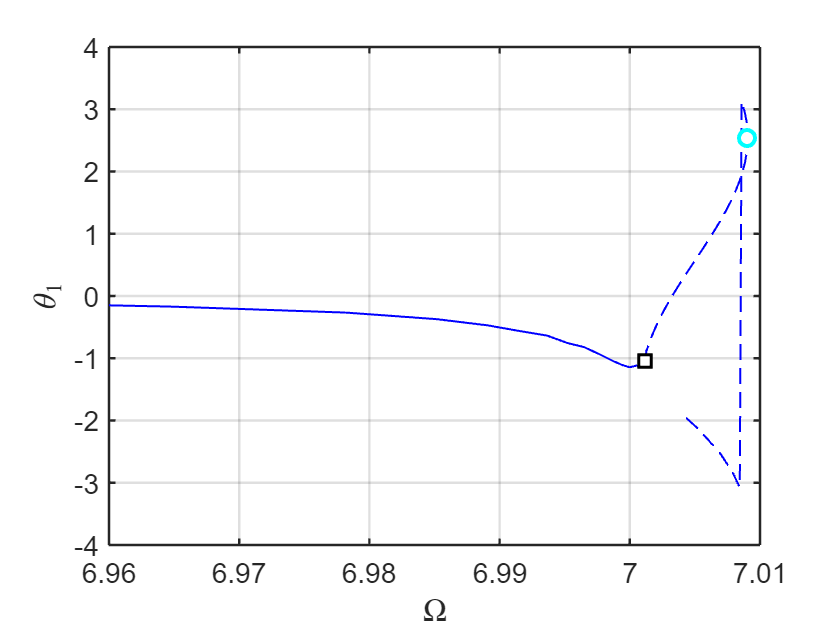

the forcing frequency 6.9600e+00 is nearly resonant with the eigenvalue -6.1884e-03 + i7.0005e+00
the forcing frequency 6.9649e+00 is nearly resonant with the eigenvalue -6.1884e-03 + i7.0005e+00
the forcing frequency 6.9782e+00 is nearly resonant with the eigenvalue -6.1884e-03 + i7.0005e+00
the forcing frequency 6.9851e+00 is nearly resonant with the eigenvalue -6.1884e-03 + i7.0005e+00
the forcing frequency 6.9891e+00 is nearly resonant with the eigenvalue -6.1884e-03 + i7.0005e+00
the forcing frequency 6.9918e+00 is nearly resonant with the eigenvalue -6.1884e-03 + i7.0005e+00
the forcing frequency 6.9936e+00 is nearly resonant with the eigenvalue -6.1884e-03 + i7.0005e+00
the forcing frequency 6.9952e+00 is nearly resonant with the eigenvalue -6.1884e-03 + i7.0005e+00
the forcing frequency 6.9965e+00 is nearly resonant with the eigenvalue -6.1884e-03 + i7.0005e+00
the forcing frequency 6.9976e+00 is nearly resonant with the eigenvalue -6.1884e-03 + i7.0005e+00
the forcing frequenc

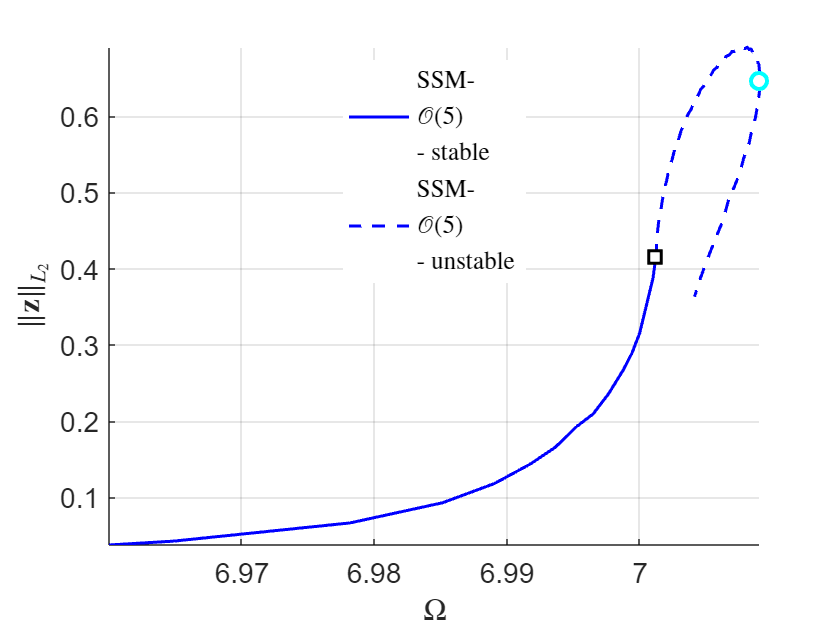

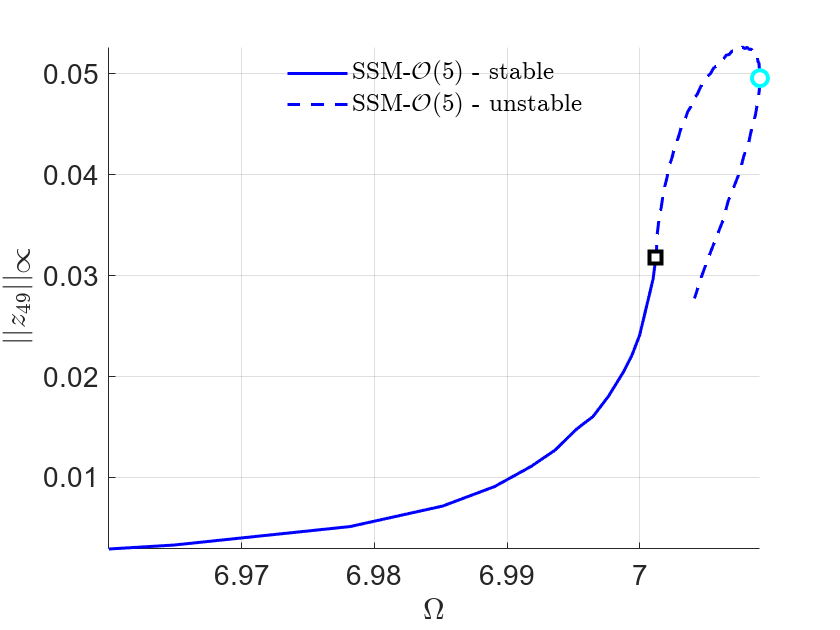

% Damped backbone curve using SSMs
% Obtaining *forced response curve* in reduced-polar coordinate

order = 5; % SSM approximation order
outdof = n-1; %[n-1 n 2*n-1 2*n]; % degree of freedom at which output is displayed
freqRange = [6.96 7.04];
mFreq = 1;
set(S.FRCOptions, 'initialSolver', 'fsolve');   % solver for initial solution
set(S.FRCOptions, 'coordinates','cartesian'); set(S.Options, 'COMPtype', 'first');
set(S.contOptions, 'h0',1e-1,'h_min',1e-3,'h_max',5, 'PtMX', 250);  % continuation setting
optdof = outdof;
epsRange = [0.01 5]*epsilon;
parRange = {freqRange,epsRange};

FRC_lead = S.SSM_isol2ep('isol_inf_lead',masterModes, order, mFreq, 'freq', freqRange,outdof);

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

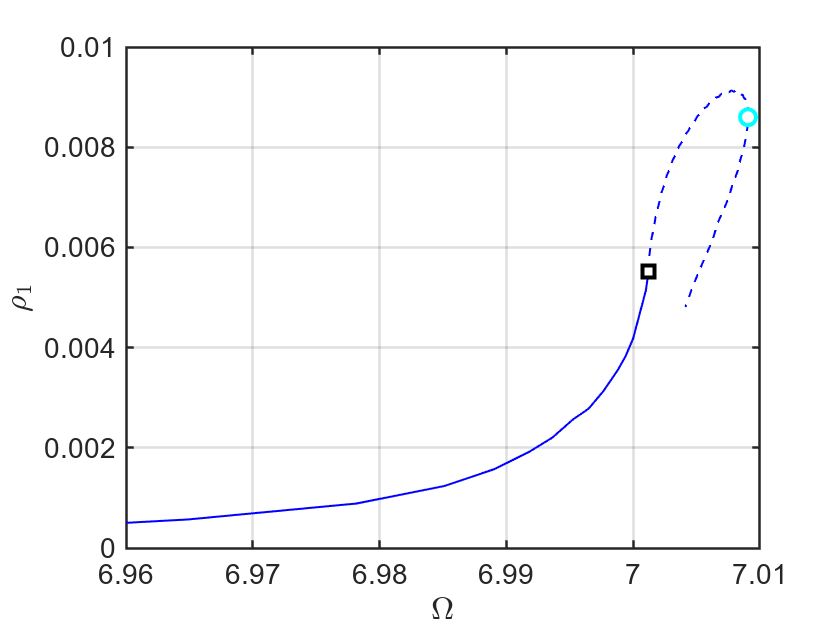

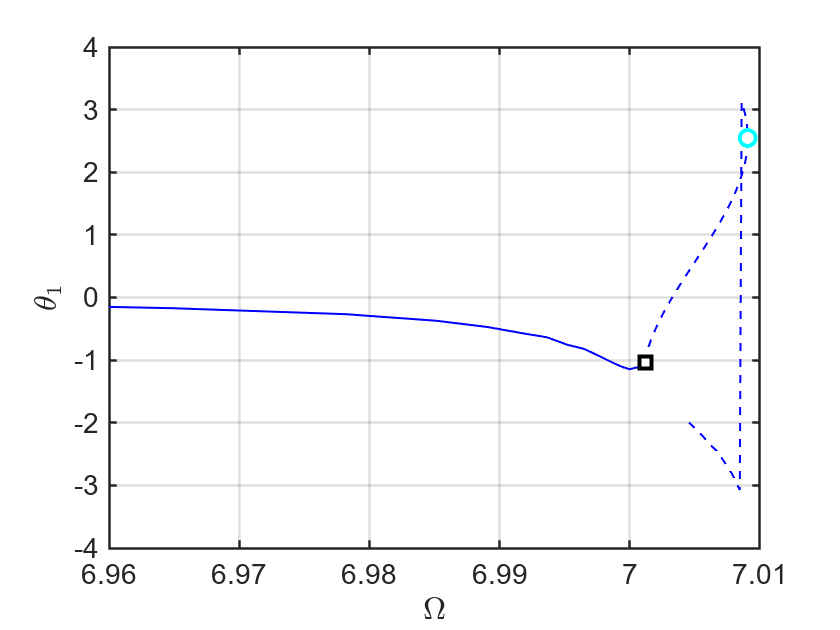

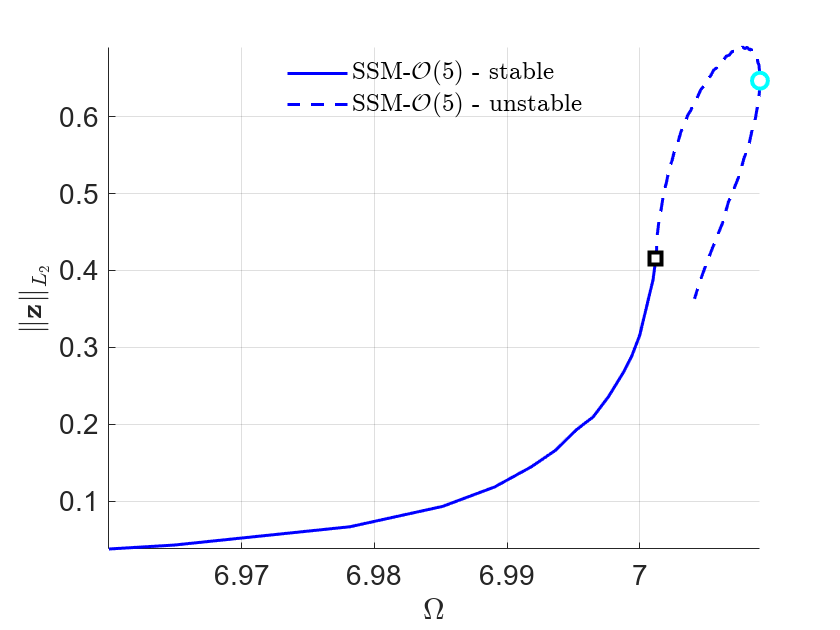

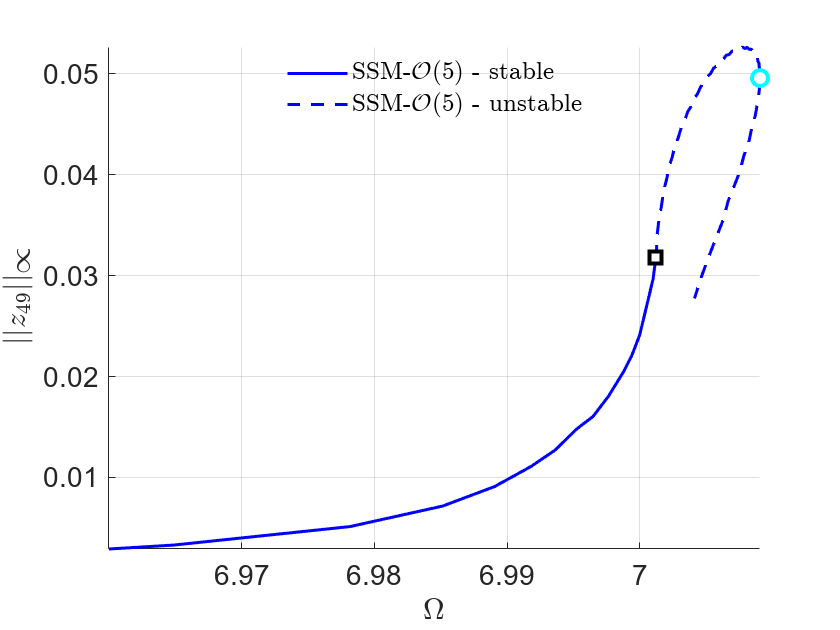

set(S.Options, 'contribNonAuto',false);
FRC_zero = S.SSM_isol2ep('isol_inf_zero',masterModes, order, mFreq, 'freq', freqRange,outdof);

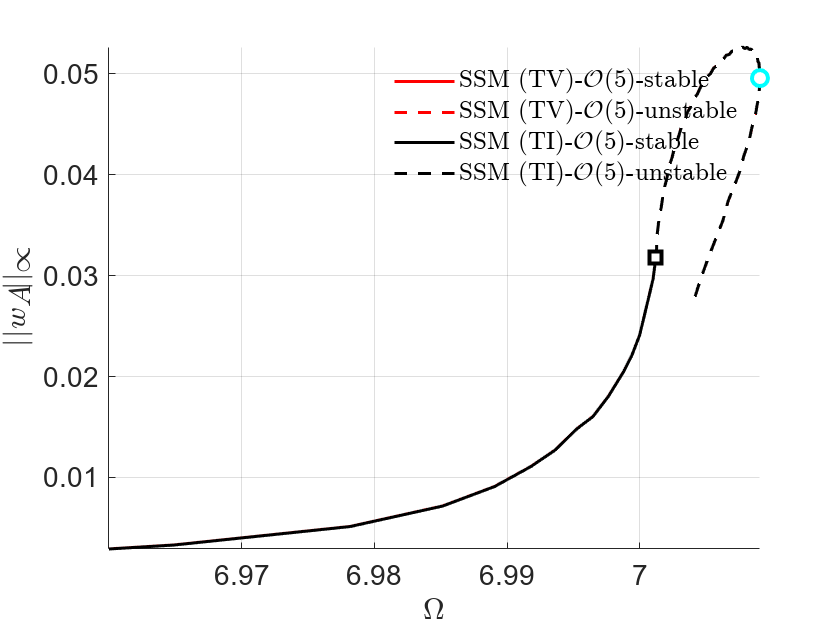


% comparision of results
FRCs = {FRC_lead,FRC_zero};
thm = struct();
thm.SN = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'cyan', 'Marker', 'o', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'cyan', 'MarkerFaceColor', 'white'};
thm.HB = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'black', 'Marker', 's', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'black', 'MarkerFaceColor', 'white'};
color = {'r','k','m','b','g'};
figure;
ax1 = gca;
for k=1:2
    FRC = FRCs{k};
    SNidx = FRC.SNidx;
    HBidx = FRC.HBidx;
    FRC.st = double(FRC.st);
    FRC.st(HBidx) = nan;
    FRC.st(SNidx) = nan;
    % color
    ST = cell(2,1);
    ST{1} = {[color{k},'--'],'LineWidth',1.5}; % unstable
    ST{2} = {[color{k},'-'],'LineWidth',1.5};  % stable
    if k==1
    legs = 'SSM (TV)-$\mathcal{O}(5)$-unstable';
    legu = 'SSM (TV)-$\mathcal{O}(5)$-stable';
    else
    legs = 'SSM (TI)-$\mathcal{O}(5)$-unstable';
    legu = 'SSM (TI)-$\mathcal{O}(5)$-stable';        
    end
    hold(ax1,'on');
    plot_stab_lines(FRC.om,FRC.Aout_frc(:,1),FRC.st,ST,legs,legu);
    SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,1),thm.SN{:});
    set(get(get(SNfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
    HBfig = plot(FRC.om(HBidx),FRC.Aout_frc(HBidx,1),thm.HB{:});
    set(get(get(HBfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');   
    xlabel('$\Omega$','Interpreter','latex'); 
    ylabel('$||w_A||_{\infty}$','Interpreter','latex'); 
    set(gca,'FontSize',14);
    grid on; axis tight; 
end
legend boxoff

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

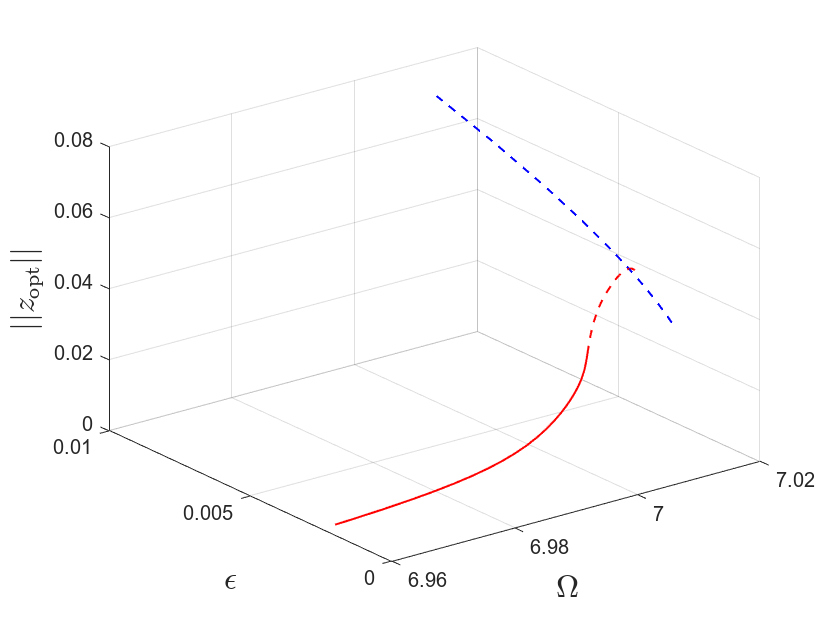


%
set(S.FRCOptions,'DBCobjnorm','linf','DBCstepFactor', [100 1000]);
set(S.FRSOptions, 'calFRS', true);
S.extract_ridges_trenches('bcssm-top-inf',masterModes,order,mFreq,parRange,outdof,optdof);

We observed that the response amplitude at $\epsilon\to0$ is not zero. This indicates the existence of isola. In order to obtain another branch of solution, we start with a solution with smaller forcing amplitude.

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

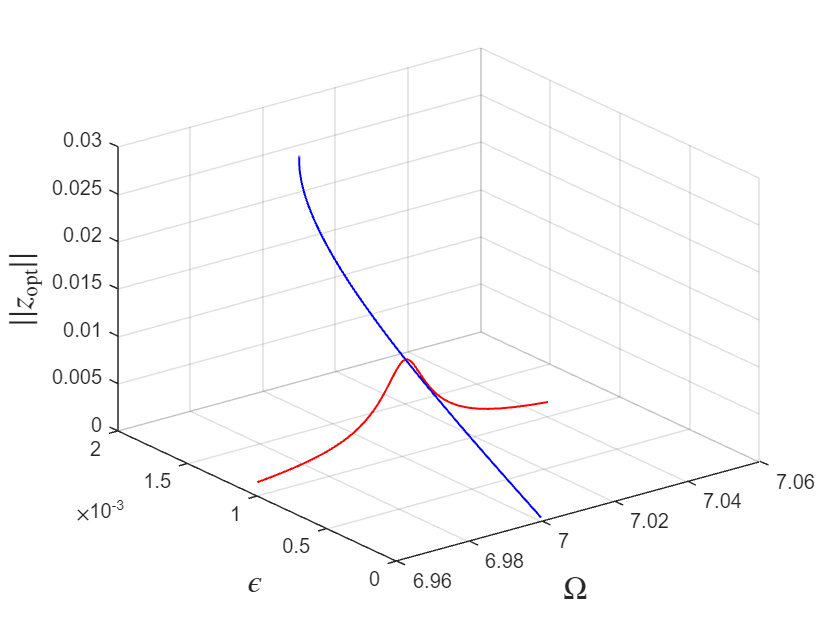

p0 = [6.96 0.5*epsilon]';
z0 = [1e-3 0]';
set(S.contOptions, 'h0',1e-3,'h_min',1e-3,'h_max',5, 'PtMX', 250);  % continuation setting
S.extract_ridges_trenches('bcssm-bot-inf',masterModes,order,mFreq,parRange,outdof,optdof,{p0,z0});

Now we plot the results at the same figure

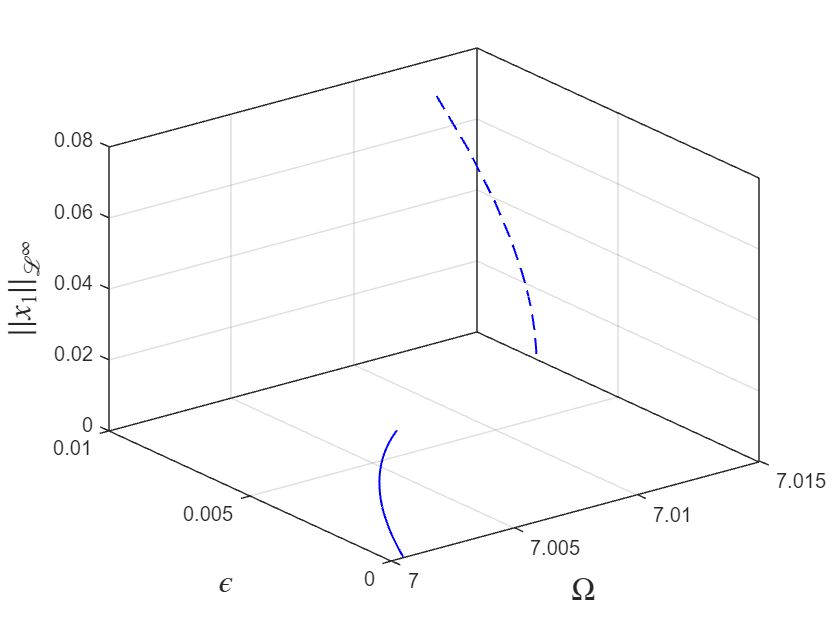

thm = struct( 'special', {{'SN', 'HB' 'BP'}});
thm.SN = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'cyan', 'Marker', 'o', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'cyan', 'MarkerFaceColor', 'white'};
thm.HB = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'black', 'Marker', 's', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'black', 'MarkerFaceColor', 'white'};
thm.lspec = {{'r-'  'LineWidth'  [1]},{'r--'  'LineWidth'  [1]}};
figure;
% Dambed backbone curves
coco_plot_bd('bcssm-top-inf.freq.bc1','om','eps','obj',@(x) abs(x)); hold on
coco_plot_bd('bcssm-bot-inf.freq.bc1','om','eps','obj',@(x) abs(x)); 
xlabel('$\Omega$','Interpreter',"latex",'FontSize',16);
ylabel('$\epsilon$','Interpreter',"latex",'FontSize',16);
zlabel('$||x_1||_{\mathcal{L}^\infty}$','Interpreter',"latex",'FontSize',16);
grid on;
box on

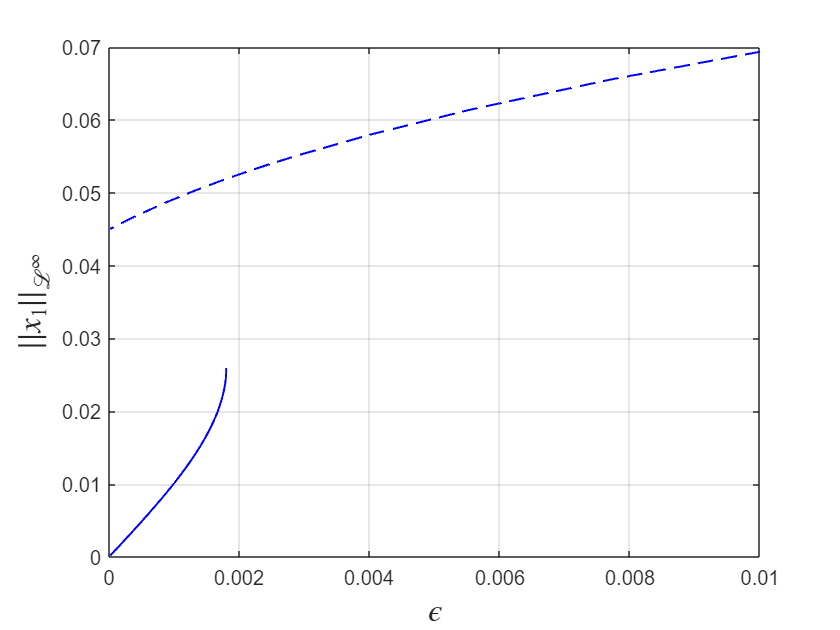

dbcplot = gcf;
figure;
coco_plot_bd('bcssm-top-inf.freq.bc1','eps','obj',@(x) abs(x)); hold on
coco_plot_bd('bcssm-bot-inf.freq.bc1','eps','obj', @(x) abs(x)); 
xlabel('$\epsilon$','Interpreter',"latex",'FontSize',16);
ylabel('$||x_1||_{\mathcal{L}^\infty}$','Interpreter',"latex",'FontSize',16);
grid on;

dbcepsplot = gcf;

The results above are maixmum solutions. For an isola, there exists a local minium as well. The algorithm here also supports the computation of minimum solutions. To see that, we calcualte FRC with proper forcing amplitude

% So we perform another computation with a solution on the isola as initial point. (the continuation from the top point get stuck at a point again)

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

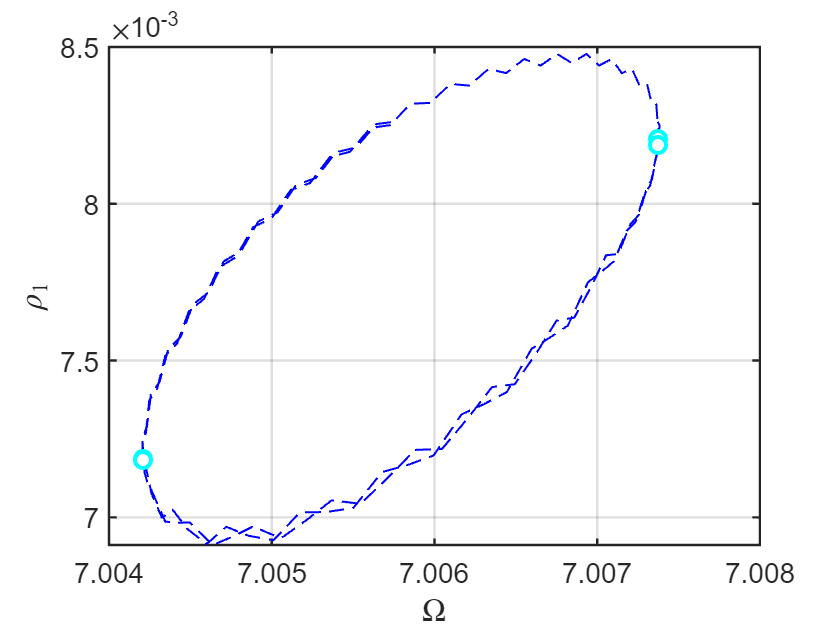

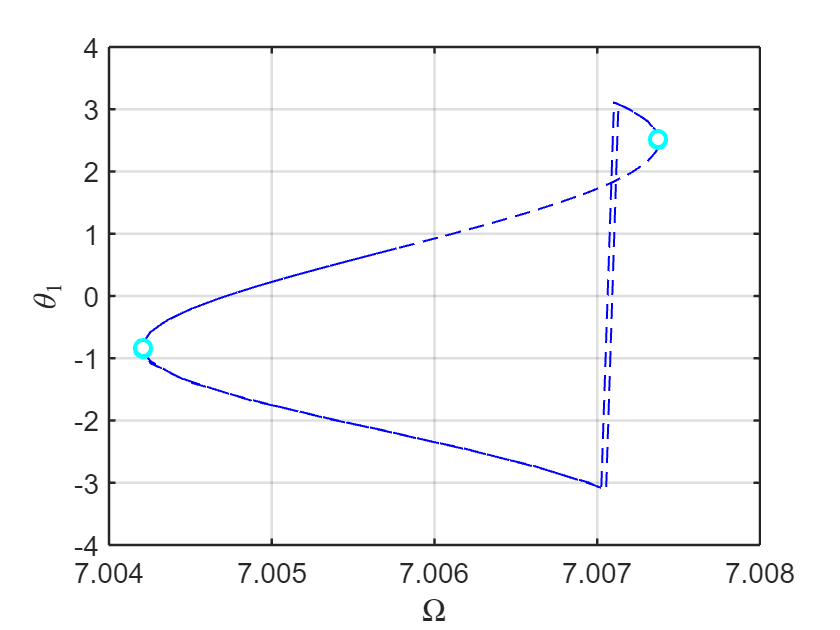

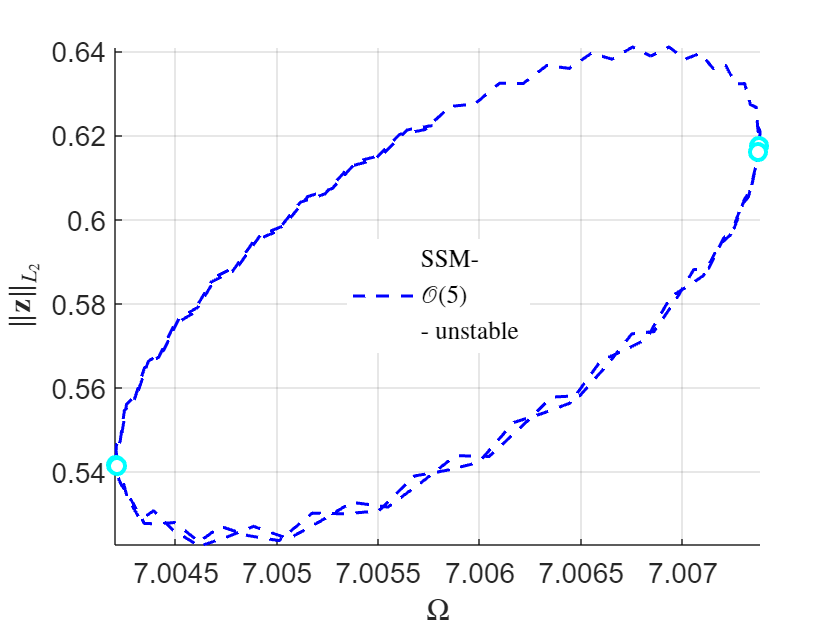

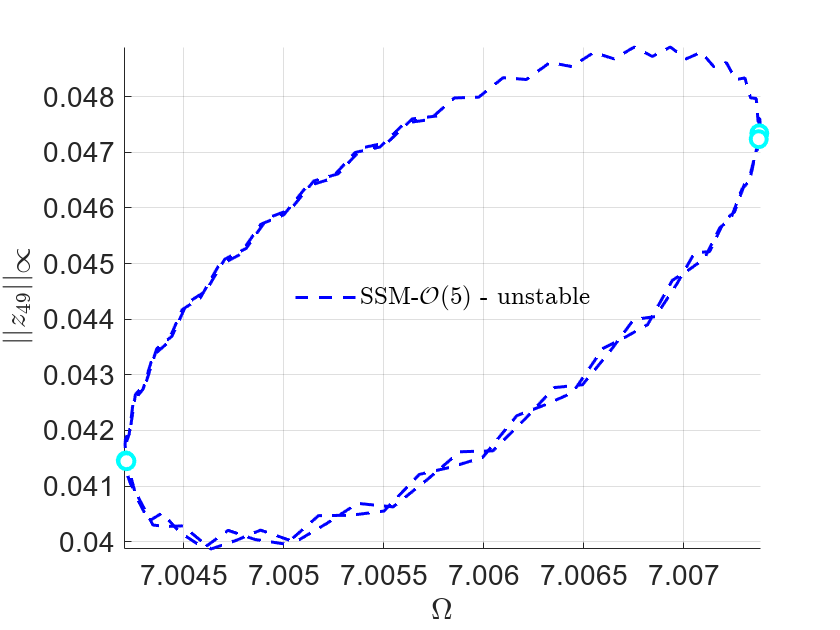

sol = ep_read_solution('bcssm-top-inf.freq.bc1',5);
set(S.contOptions, 'PtMX', [60 60]);
set(S.contOptions, 'h0',1e-3,'h_min',1e-3,'h_max',5)
S.SSM_isol2ep('isola-inf',masterModes,order,mFreq,'freq',freqRange,outdof,{sol.p,sol.x});

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

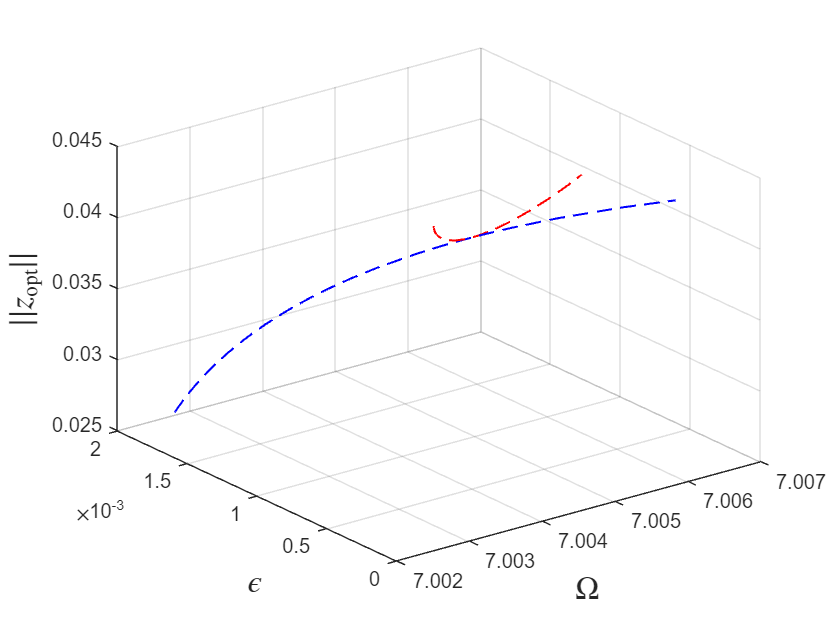

set(S.FRCOptions,'DBCstepFactor', [100 100]);
sol = ep_read_solution('isola-inf.ep',6);
S.extract_ridges_trenches('bcssm-mid-inf',masterModes,order,mFreq,parRange,outdof,optdof,{sol.p,sol.x});

Now we plot the results of the minimum branch along with the maximum solutions

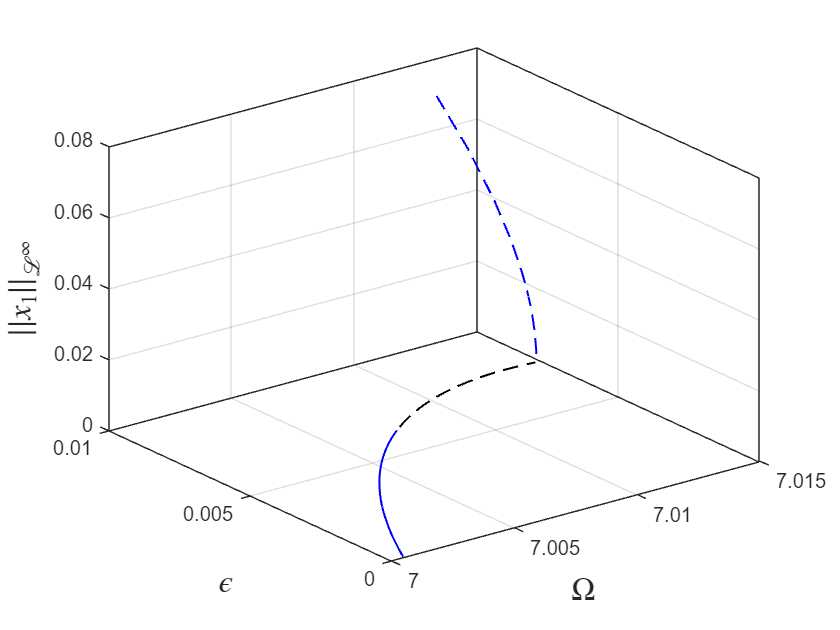

thm2.lspec = {{'k-'  'LineWidth'  [1]},{'k--'  'LineWidth'  [1]}};
figure(dbcplot); hold on
% Dambed backbone curves
coco_plot_bd(thm2,'bcssm-mid-inf.freq.bc1','om','eps','obj',@(x) abs(x)); 
xlabel('$\Omega$','Interpreter',"latex",'FontSize',16);
ylabel('$\epsilon$','Interpreter',"latex",'FontSize',16);
zlabel('$||x_1||_{\mathcal{L}^\infty}$','Interpreter',"latex",'FontSize',16);
grid on;
box on

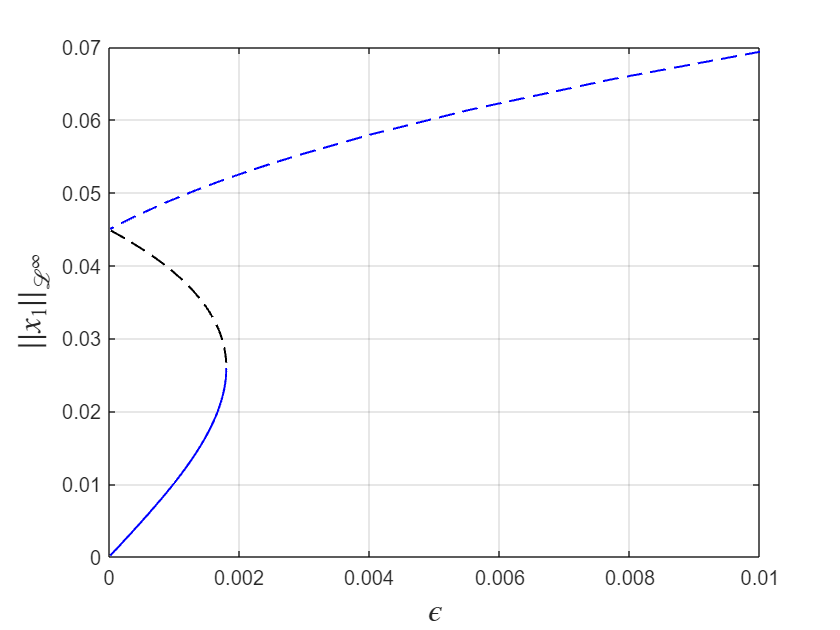

figure(dbcepsplot); hold on
coco_plot_bd(thm2,'bcssm-mid-inf.freq.bc1','eps','obj',@(x) abs(x)); 
xlabel('$\epsilon$','Interpreter',"latex",'FontSize',16);
ylabel('$||x_1||_{\mathcal{L}^\infty}$','Interpreter',"latex",'FontSize',16);
grid on;